# RESULT: Arm Shape Comparison

*MATLAB Version: '23.2.0.2409890 (R2023b) Update 3'*

*Last revised: 8/17/2024*

*Authors: Bill Fan*

This document should contain all that is necessary for the RESULTS subsection on applying the attainability methods for comparing different overall arm shapes for reaching a specific tip pose and load configuration.

First, we will define a target task, which comprises of a target tip pose and tip load. For this example we will approximate a drawer-opening task.

%% Step 1: Define target trajectory keybpoints
% Base pose: hanging down
pose_base = [0; 0; -pi/2];
g_0 = Pose2.hat(pose_base);

% Keypoint poses: [x y theta]
pose_1 = [0.35; -0.3; 0];

poses = [pose_1];

% Create load vector
qx = 5; % Load of opening the drawer: 1N
w_tip = [qx; 0; 0]; % If we move to the left to open the drawer, then the drawer force will pull to the right

We will compare a variety of "heuristic" based shape-planning methods. Each heuristic is formulated as a cost function - for example, the observation "the best shape minimizes curvatures" associates each arm shape's cost with the sum of the curvatures.

% Step 2: 
N_nodes = 10;

cell_cost_funcs = {
    @(mat_geom) base_curve_cost_sum_of_dists_from_target_squared(mat_geom, [50, 1], 0.50), ...
    @(mat_geom) base_curve_cost_sum_of_dists_from_target_squared(mat_geom, [40, 1], 0.51), ...
    @(mat_geom) base_curve_cost_minimum_change_in_curvature(mat_geom, [20, 0, 1], 0.50), ...
};
names = ["[50, 1]", "[40, 1]", "[20, 1] - min diff"];
N_shapes = length(cell_cost_funcs);

cell_segment_twists = cell(size(cell_cost_funcs));

for i_shape = 1 : numel(cell_segment_twists)
    cost_func_i = cell_cost_funcs{i_shape};
    cell_segment_twists(i_shape) = find_shape_single_seg(pose_base, poses, w_tip, N_nodes, cost_func_i);
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

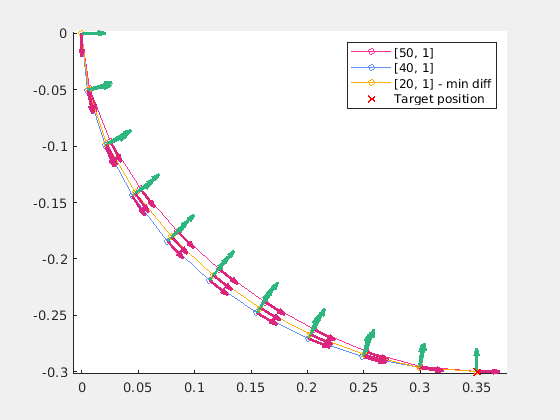


ax = axes(figure("Visible", true));
hold on;

color_green = [45 182 125] / 255;
color_yellow = [255 176 0] / 255;
color_blue = [100 143 255] / 255;
color_red = [255 48 150] / 255;

colors = [color_red; color_blue; color_yellow; color_green];

colors = [colors; colors];

for i_shape = 1 : numel(cell_segment_twists)
    segment_twists_i = cell_segment_twists{i_shape};
    poses_i = calc_poses(g_0, segment_twists_i);
    linestyle = struct("color", colors(i_shape, :), "Marker", "o", "Markersize", 5, "Displayname", names(i_shape));
    plot_poses(poses_i, ax, linestyle, true);
end
plot(poses(1, :), poses(2, :), 'rx', "MarkerSize", 7, "Linewidth", 2, "Displayname", "Target position")
legend()

We will now propose an arm design and evaluate it across these potential ways of reaching the target.

rho_outer = 0.02;
rho_inner = 0.00;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
    1, 1, 1, 1;
    0, 0, 0, 0;
    -rhos;
    ];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.51;

p_bounds = [50; 100; 100; 50];

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;
struct_design.p_bounds = p_bounds;

Now, for each arm backbone shape we will compute the reaction-requirements at each point along the arm, induced by the tip-load requirement. 

cell_q = cell(size(cell_segment_twists));
qf_all = zeros(N_nodes, N_shapes);
qm_all = zeros(N_nodes, N_shapes);

for i_shape = 1 : numel(cell_segment_twists)
    q_i = calc_external_wrench(cell_segment_twists{i_shape}, w_tip, g_0);
    qf_all(:, i_shape) = q_i(1, :);
    qm_all(:, i_shape) = q_i(3, :);

    cell_q{i_shape} = q_i;
end

For each arm shape, plot its absolute and relative reaction prisms, with the corresponding requirement traces.

for i_shape = 1 : numel(cell_segment_twists)
    
end

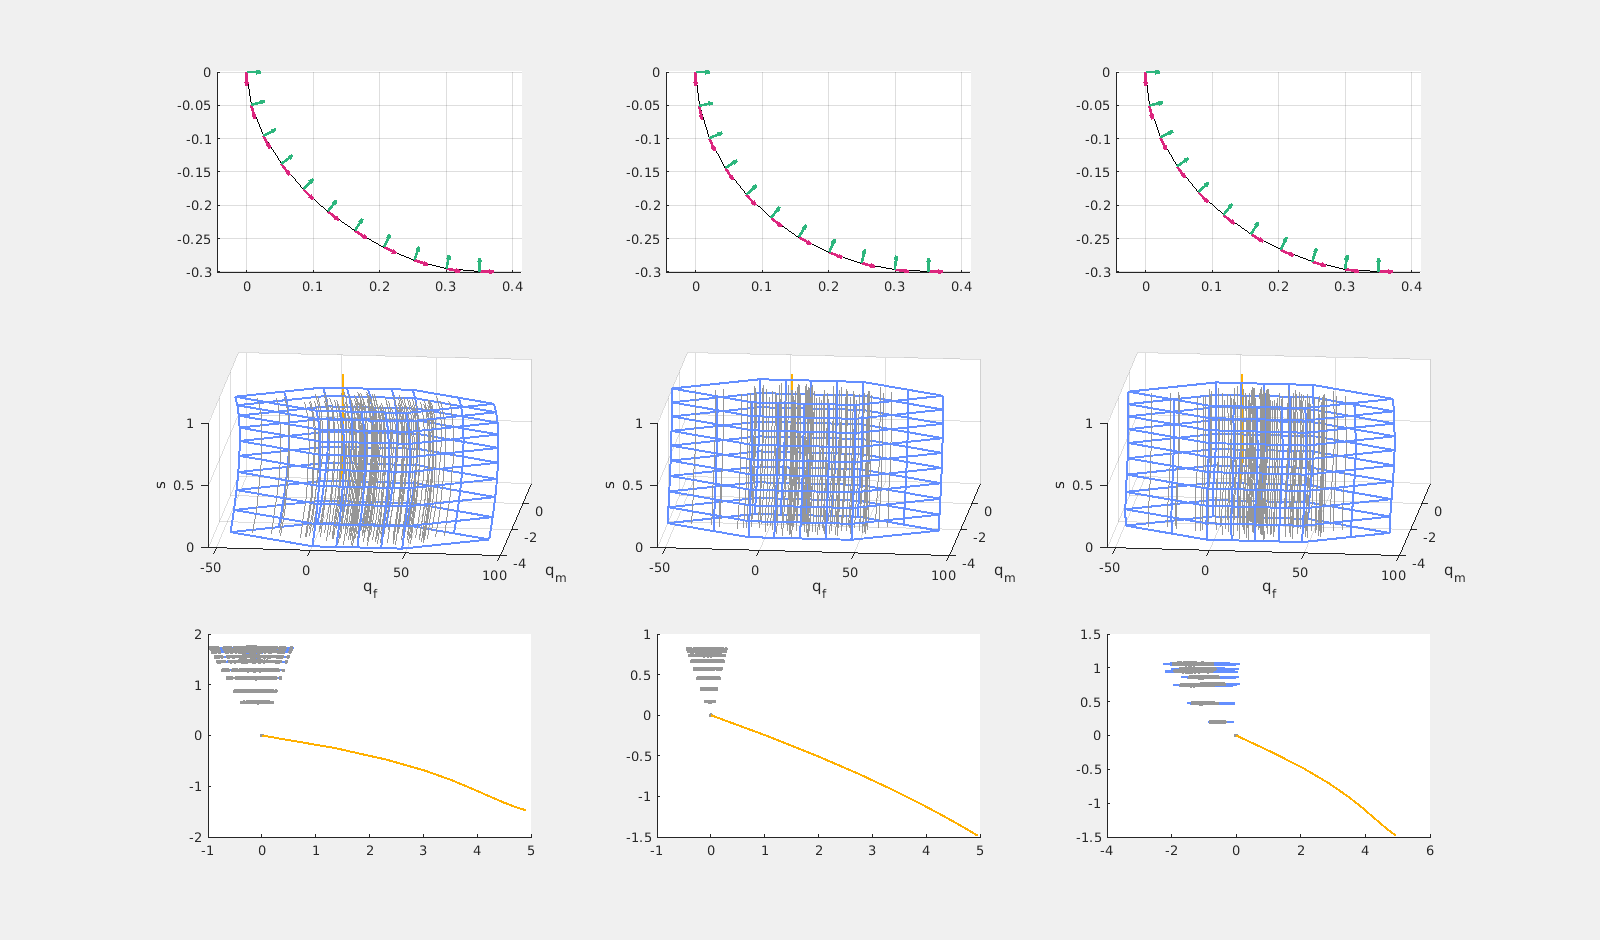



fig = figure("Visible", true, "Position", [0, 0, 1600, 1050]);
for i = 1 : numel(cell_segment_twists)
    ax = subplot(3, 3, i);
    hold on
    segment_twists_ij = cell_segment_twists{i};
    poses = calc_poses(g_0, segment_twists_ij);
    plot_poses(poses, ax);

    grid on
end
linkaxes(fig.Children)

%%% Row 2: attainable absolute reaction space
% Plot the absolute rxn prisms
s = linspace(0, 1, N_nodes);

N_test_ps = 100;
p_sample = diag(struct_design.p_bounds) * unifrnd(0, 1, 4, N_test_ps);
mat_s_p_sample = repmat(s, [N_test_ps, 1]);
color_gray = [150,150,150]/255;
axs_row = cell(size(cell_segment_twists));
for i_shape= 1 : numel(cell_segment_twists)
    axs_row{i_shape} = subplot(3, 3, i_shape + 3);
    hold on

    % Get all of the boundary traces for this shape
    segment_twists_i = cell_segment_twists{i_shape};
    [bndry_af_i, bndry_am_i] = compute_attainable_wrench_space(segment_twists_i, struct_design);
    i_bndry = boundary(bndry_af_i(1, :)', bndry_am_i(1, :)', 0);
    mat_s = repmat(s, [size(bndry_af_i, 2), 1]);

    [interior_af_i, interior_am_i] = compute_reaction_traces(p_sample, segment_twists_i, struct_design);

    plot3(bndry_af_i(:, i_bndry)', bndry_am_i(:, i_bndry)', s, color=color_blue, linewidth=1.5);
    plot3(bndry_af_i(:, i_bndry)', bndry_am_i(:, i_bndry)', mat_s(i_bndry, :), color=color_blue, linewidth=1.5);

    plot3(qf_all(:, i_shape), qm_all(:, i_shape), mat_s', "color", color_yellow, "linewidth",1.5);

    plot3(interior_af_i, interior_am_i, mat_s_p_sample, color=color_gray);
    
    xlabel("q_f")
    ylabel("q_m")
    zlabel("s")
    grid on
    view(6, 30);
end
linkaxes([axs_row{:}]);

% Row 3 - relative reaction traces
rltv_qf = qf_all - qf_all(1, :);
rltv_qm = qm_all - qm_all(1, :);
for i_shape = 1 : numel(cell_segment_twists)
    subplot(3, 3, i_shape + 6);

    segment_twists_i = cell_segment_twists{i_shape};
    [bndry_af_i, bndry_am_i] = compute_attainable_wrench_space(segment_twists_i, struct_design);
    [cell_afs, cell_ams] = relative_attainable_wrench_hull(bndry_af_i, bndry_am_i);

    [interior_af_i, interior_am_i] = compute_reaction_traces(p_sample, segment_twists_i, struct_design);
    rltv_interior_af_i = interior_af_i - interior_af_i(1, :);
    rltv_interior_am_i = interior_am_i - interior_am_i(1, :);

    hold on
    for i = 1 : N_nodes
        plot(cell_afs{i}, cell_ams{i}, "-", color=color_blue, markerfacecolor=color_blue, markersize=3, linewidth=1.5);
    end

    plot(rltv_interior_af_i, rltv_interior_am_i, '.',color=color_gray);
    plot(rltv_qf(:, i_shape), rltv_qm(:, i_shape), color=color_yellow, linewidth=1.5)
end

% For each target shape, compute the closest attainable shape to it.
residuals = zeros(1, N_shapes);
p_solns = zeros(4, N_shapes);
cell_closest_twists = cell(1, N_shapes);
for i = 1 : N_shapes
    [residuals(i), p_solns(:, i)] = find_p_to_match_loaded_shape(cell_segment_twists{i}, w_tip, struct_design);

    cell_closest_twists{i} = solve_equilibrium_shape(N_nodes, struct_design, p_solns(:, i), w_tip);
end

color_green = [45 182 125] / 255;
color_yellow = [255 176 0] / 255;
color_blue = [100 143 255] / 255;
color_red = [255 48 150] / 255;
colors = [color_red; color_blue; color_green];

% Lighter colors
color_light_green = [130 205 174] / 255;
color_light_yellow = [248 203 97] / 255;
color_light_blue = [135 167 250] / 255;
color_light_red = [230 100 164] / 255;

% Darker colors
color_dark_green = [0.0706    0.5137    0.3294];
color_dark_blue = [0.2941    0.4196    0.7490];
color_dark_yellow = [0.7490    0.5176         0];
color_dark_red = [0.6549    0.1059    0.3725];
colors_dark = [color_dark_red; color_dark_blue; color_dark_green];

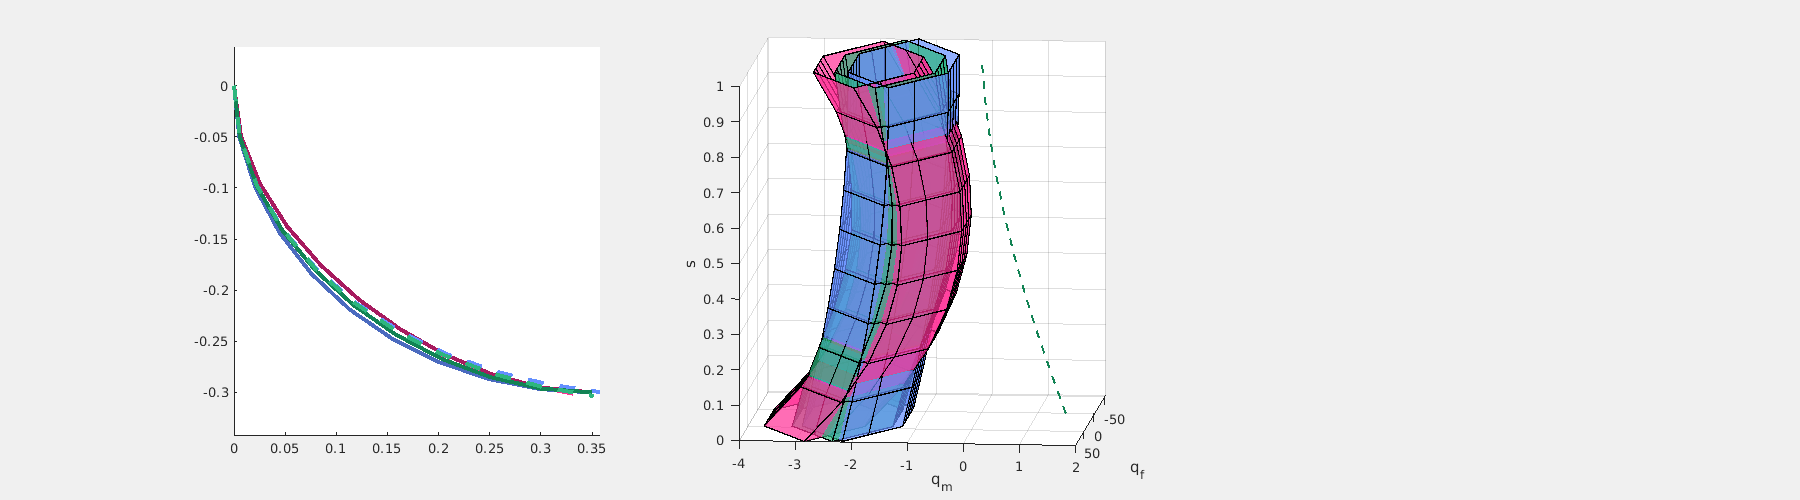

figure("Visible", true, "Position", [0, 0, 1800, 500]);
ax = subplot(1, 3, 1);
hold on

for i = 1 : N_shapes
    target_poses_i = calc_poses(g_0, cell_segment_twists{i});
    closest_poses_i = calc_poses(g_0, cell_closest_twists{i});
    
    plot_poses(target_poses_i, ax, struct("color", colors_dark(i, :), "linewidth", 3), false);
    plot_poses(closest_poses_i, ax, struct("color", colors(i, :), "linestyle", "--", "linewidth", 3), false);
end
ax = subplot(1, 3, 2);
hold on

for i = 1 : N_shapes
    segment_twists_i = cell_segment_twists{i};
    [bndry_af_i, bndry_am_i] = compute_attainable_wrench_space(segment_twists_i, struct_design);
    i_bndry = boundary(bndry_af_i(1, :)', bndry_am_i(1, :)', 0);

    plot_wrench_hull(bndry_af_i(:, i_bndry), bndry_am_i(:, i_bndry), ax, colors(i, :), struct("facealpha", 0.7, "linewidth", 1));

    plot3(qf_all(:, i_shape), qm_all(:, i_shape), mat_s', "color", colors_dark(i, :), "linestyle", "--", "linewidth",1.5);
end
xlabel("q_f")
ylabel("q_m")
zlabel("s")
grid on
view(95, 8)

function cost = base_curve_cost_sum_of_dists_from_target_squared(mat_geom, w, target_l)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    all_twists = [cell_g_circ_right{:}];
    all_ls = all_twists(1, :);
    all_curvatures = all_twists(3, :);

    dist_from_target_l = all_ls - target_l;
    indiv_costs = [norm(dist_from_target_l); norm(all_curvatures)];
    cost = dot(w, indiv_costs);
end

function cost = base_curve_cost_minimum_change_in_curvature(mat_geom, w, target_l)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    all_twists = [cell_g_circ_right{:}];
    all_ls = all_twists(1, :);
    all_curvatures = all_twists(3, :);

    dist_from_target_l = all_ls - target_l;
    indiv_costs = [norm(dist_from_target_l); norm(all_curvatures); norm(diff(all_curvatures))];
    cost = dot(w, indiv_costs);
end

function mat_g_circ_right = v_geom_to_g_circ(v_geom)
    % Convert a "geometry vector" to a matrix of twists
    % By "geometry vector" I mean [l_1; k_1; l_2; k_2; ...; l_n; k_n]
    n_g_circ = length(v_geom)/2;
    mat_l_k = reshape(v_geom, [2, n_g_circ]);
    lengths = mat_l_k(1, :);        % lengths
    shears = zeros(1, n_g_circ);    % shears
    curvatures = mat_l_k(2, :);     % curvatures

    mat_g_circ_right = [lengths; shears; curvatures];
end

function cell_g_circ_out = mat_geom_to_g_circ(mat_geom)
    % Convert a "geometry matrix" to a cell array of matrices of twists
    
    N_poses = size(mat_geom, 2);
    N_segs = size(mat_geom, 1) / 2;
    cell_g_circ_out = cell(1, N_poses);
    for i = 1 : N_poses
        v_geom_i = mat_geom(:, i);
        cell_g_circ_out{i} = v_geom_to_g_circ(v_geom_i);
    end
end

function [boundary_af, boundary_qf] = compute_attainable_wrench_space(mat_segment_twists, struct_design)
    boundary_ps = sample_edges_of_cuboid(3, struct_design.p_bounds);
    
    [boundary_af, boundary_qf] = compute_reaction_traces(boundary_ps, mat_segment_twists, struct_design);
end

function [cell_rltv_bndry_af_per_node, cell_rltv_bndry_am_per_node] = relative_attainable_wrench_hull(bndry_af, bndry_am)
    N_nodes = size(bndry_af, 1);

    cell_rltv_bndry_af_per_node = cell(1, N_nodes);
    cell_rltv_bndry_am_per_node = cell(1, N_nodes);

    cell_rltv_bndry_af_per_node{1} = [0, 0];
    cell_rltv_bndry_am_per_node{1} = [0, 0];

    % Compute all the relative attainble reaction traces
    % These points will form the boundary of the relatively attainable
    % reaction space for each node. 
    rltv_bndry_af = bndry_af - bndry_af(1, :);
    rltv_bndry_am = bndry_am - bndry_am(1, :);

    for i = 2 : N_nodes
        % Order the points for each node, and only keep the ones that
        % contribute to the convex hull
        i_bndry = boundary(rltv_bndry_af(i, :)', rltv_bndry_am(i, :)', 0);

        cell_rltv_bndry_af_per_node{i} = rltv_bndry_af(i, i_bndry);
        cell_rltv_bndry_am_per_node{i} = rltv_bndry_am(i, i_bndry);
    end
end